# Trotter Error Analysis

Here we analysis the trotter error. As mentioned in the paper "A Theory of Trotter Error", we can express the error in 3 types, and for our purpose, the exponential type error is perticularly convenient because it allows us to transform the trotter error to the error of input matrix A. 

## Numerical Bound for | A' - A |

## bound for |A' - A|

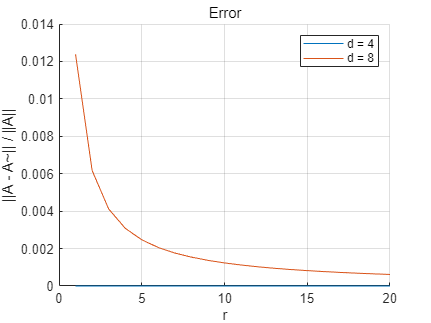


% sample range
ds = [4,8];
rs = 1:20; 
figure;
hold on;

for d = ds
    s = floor(log2(d));
    As = genSparse(d,s,6*s^2,0.8); 
    t = 0.1;

    epss = zeros(1, length(rs)); 
    for idx = 1:length(rs)
        r = rs(idx);
        epss(idx) = epsA(As,t,r);
    end

    plot(rs,epss,'DisplayName',sprintf('d = %d',d));
end

xlabel('r');
ylabel('||A - A~|| / ||A||');
title('Error');
legend show;
grid on;
hold off;

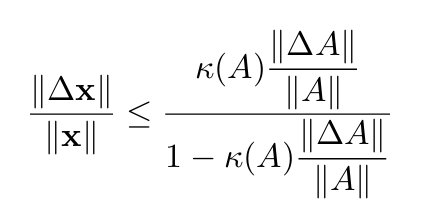

Now we can bound the error introduced by trotter using this formula. From the experiment we know that using r = 10, we can bound ||delta A|| / ||A|| to be roughly 0.01. If we set the condition number of A to be less than 5, then the relative error of this step is approximately less than 0.05.

Next we look at the scaling with respect to n

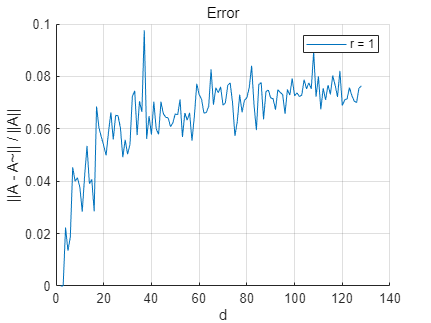

r = 1;
ds = 2:128; 
t = 0.1;

figure;
hold on;
epss = zeros(1, length(ds)); 
for idx = 1:length(ds)
    d = ds(idx);
    s = floor(log2(d));
    As = genSparse(d,s,6*s^2,0.2);
    epss(idx) = epsA(As,t,r);
end

plot(ds,epss,'DisplayName',sprintf('r = %d',r));


xlabel('d');
ylabel('||A - A~|| / ||A||');
title('Error');
legend show;
grid on;
hold off;

Now let's see the dependence with respect to t.

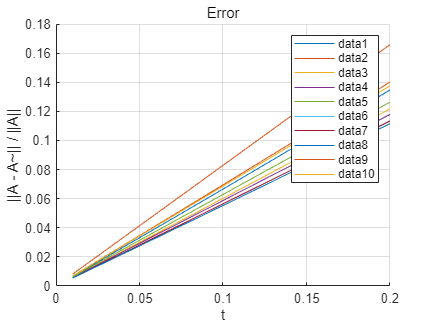

d = 32;
r= 1; 
ts = 0.01:0.01:0.2;
n = 10;

figure;
hold on;


s = floor(log2(d));

for data = 1:10


    As = genSparse(d,s,6*s^2,0.2);
    epss = zeros(1, length(ts)); 
    for idx = 1:length(ts)
        t = ts(idx);
        epss(idx) = epsA(As,t,r);
    end
    
    plot(ts,epss);

end

xlabel('t');
ylabel('||A - A~|| / ||A||');
title('Error');
legend show;
grid on;
hold off;

## Distribution

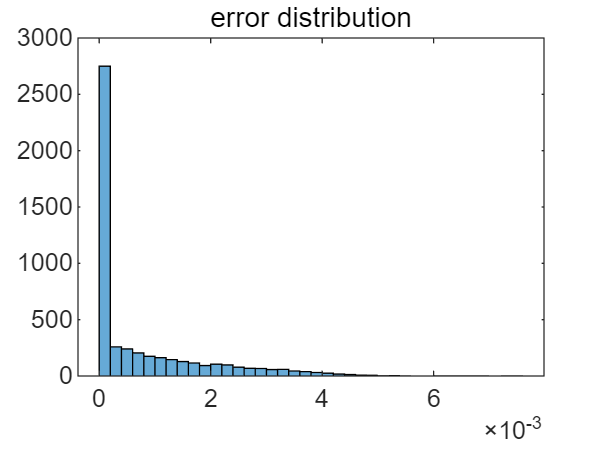

function [eps] = epseA(As,t,r)
    A = full(sumSparse(As)); 
    troExpA = trotter(As,t,r); 
    eps = norm(troExpA - expm(1i * A * t), 2);
end

n = 10000; % number of test case
d = 16; % dimension of matrix
t = 0.1;
r = 1; % we can only set r to be 1

distribution = zeros(1, n);

for idx = 1:n
    s = 3;
    As = genSparse(d,s,6*s^2,0.2);
    distribution(idx) = epseA(As,t,r);
end

histogram(distribution, 'Normalization', 'pdf');
title('error distribution');

## Extreme Case

A1 = [1,0;0,-1];
A2 = [0,1;1,0];

t = 0.1;
As = cell(1,2);
As{1} = sparse(A1);

As{2} = sparse(A2);
extremEps = epsA(As,0.1,1);
extremEps

extremEps = 0.1001